# Exercise 2 - DCT Compression

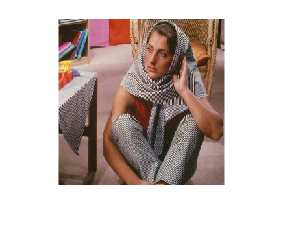

storedStruct = load("barbara.mat");
barbara = storedStruct.barbara;

imshow(barbara,[]);

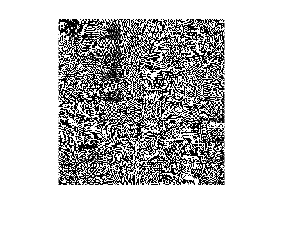



I = im2gray(barbara);
windowSize = [32 32];

dct = @(block_struct) my2D_DCT(block_struct.data);
dct_transform = blockproc(I,windowSize,dct);

imshow(dct_transform);

## Quantization - Zone Method

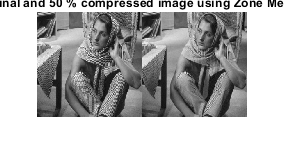

% Keeping only the top right coefficients by applying a mask to each block
% r is the percentage of information kept
MSE1 = zeros(0.5/0.05,1);

for r=0.05:0.05:0.5
    no_of_coeffs = round(windowSize(1).^2 * r ) ;
    %Creating the mask by keeping upper diagonal matrix with no_of_coeffs
    %elements
    no_of_elements = 1;
    mask = triu(ones(windowSize),no_of_elements);
    while(no_of_coeffs < nnz(mask))
        mask = triu(ones(windowSize),no_of_elements);
        no_of_elements = no_of_elements + 1;

    end

    final_mask = flip(mask,2);
    final_mask = @(block_struct) (final_mask.*block_struct.data);
    maskedBlocks = blockproc(dct_transform,windowSize,final_mask); %Apply Mask
    
    IDCT = @(block_struct) my2D_IDCT(block_struct.data); %Inverse DCT
    restoredImage = blockproc(maskedBlocks,windowSize,IDCT); %Apply inverse DCT to every 32x32 block
    
     if ((r == 0.05 ) || (r == 0.5))
        imshowpair(I,restoredImage,'montage');
        title(sprintf('Original and %d %% compressed image using Zone Method',uint8(100 - r*100)))
    end
    
    MSE1(round(r/0.05)) = sum(sum((double(I)-restoredImage).^2)) / (size(I,1) * size(I,2));

end

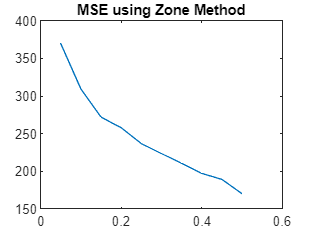


%Plotting the Mean Square Error for different information percentage 
f2 = figure;
inform_percent = 0.05:0.05:0.5;
plot(inform_percent,MSE1)
title("MSE using Zone Method");

## Quantization - Threshold method

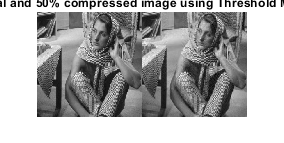

%% For each 32*32 window, we find the average pixel value and we keep each pixel that is above a certain
MSE2 = zeros(0.5/0.05,1);

for r=0.05:0.05:0.5


    thresholding = @(block_struct) threshold(r,block_struct.data);
    threshBlocks = blockproc(dct_transform,windowSize,thresholding);
    IDCT = @(block_struct) my2D_IDCT(block_struct.data); %Inverse DCT
    restoredImage = blockproc(threshBlocks,windowSize,IDCT); %Apply inverse DCT to every 32x32 block
    
 
    
    if ((r == 0.05 ) || (r == 0.5))
        imshowpair(I,restoredImage,'montage')
        title(sprintf('Original and %d%% compressed image using Threshold Method',uint8(100 - r*100)))
    end
    MSE2(round(r/0.05)) = sum(sum((double(I)-restoredImage).^2)) / (size(I,1) * size(I,2));
   
end

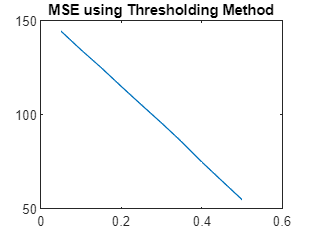



%Plotting the Mean Square Error for different information percentage 
f3 = figure;
inform_percent = 0.05:0.05:0.5;
plot(inform_percent,MSE2)
title("MSE using Thresholding Method");